close all
clear

q = 5; % quantization level
eps = 2; % privacy parameter
r=0.5; % geometric series constant

xmax = 1;
xmax = floor(xmax*q)/q; % We need to make sure they are integers
M = 2*xmax*q+1; % total amount of x samples
x_grid = linspace(-xmax,xmax,M);

amax = 5*xmax; % amax needs to be AT LEAST 2 times larger.
amax = floor(amax*q)/q; % Same as above
N = 2*amax*q+1; % total amount of a samples
a_grid = linspace(-amax,amax,N);

% We assign a distribution to X\in x_grid

% x_P = ones(1,M)/M; % Uniform distribution

x_P = x_grid.^2

x_P =     1.0000    0.6400    0.3600    0.1600    0.0400         0    0.0400    0.1600    0.3600    0.6400    1.0000


x_P = x_P./ sum(x_P);
sum(x_P)

ans = 1

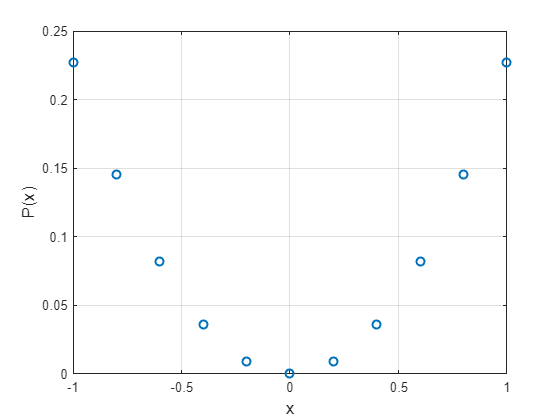

figure
plot(x_grid,x_P,'o',LineWidth=1.5);
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on

% Given the privacy parameter \epsilon, 
% we construct the comparison matrix A, 
% which contains the comparision between each pair of 
% P(a|x) vs. P(a'|x') such that a+x = a'+x'

A = zeros(1,M*N);
for k = -M+1:-1
    for i = 1:M
    for j = 1:M
        temp = zeros(M,N);
        temp(i,max(k+i,1)) = r^(abs(min(k+i-1,0)));
        if i~=j
        temp(j,max(k+j,1)) = -exp(eps)* r^(abs(min(k+j-1,0)));
        A = [A;reshape(temp',1,M*N)];
        end
    end
    end
end

for k = 1:N-M+1
    for i= 1:M
        for j = 1:M
            temp_series = zeros(1,M);
            if i~=j
            temp_series(i) = 1;
            temp_series(j) = -exp(eps);
            temp = [zeros(M,k-1),diag(temp_series),zeros(M,N-M-k+1)];
            A =[A;reshape(temp',1,M*N)];
            end
        end
    end

end

for k = N-M+1:N-1
    for i = 1:M
    for j = 1:M
        temp = zeros(M,N);
        temp(i,min(k+i,N)) = r^(abs(max(k+i-N,0)));
        if i~=j
        temp(j,min(k+j,N)) = -exp(eps)* r^(abs(max(k+j-N,0)));
        A = [A;reshape(temp',1,M*N)];
        end
    end
    end
end

% inequality constraints, 

A(1,:)=[]; % remove the intial row (empty)

b = zeros(1,(M+N-1)*(M-1)*M); % this could be the delta vector

% We form the equality contraints, 

a_matrix = zeros(M,M*N); % zero expection coefficients
for i = 1:M
    a_matrix(i,1+(i-1)*N:N+(i-1)*N) = a_grid;
end

ones_matrix = zeros(M,M*N); % probability validity coefficients
for i = 1:M
    ones_matrix(i,1+(i-1)*N:N+(i-1)*N) = ones(1,N);
end

% the equality constraint coeff matrix
Aeq = [a_matrix;ones_matrix];
% the vector
beq = [zeros(M,1); ones(M,1)];

Asq = a_matrix.^2;

lb = zeros(1,M*N);
ub = [];
obj = x_P*Asq;
xVector=linprog(obj,A,b,Aeq,beq,lb,ub);

Optimal solution found.



% (a_matrix*xVector)'
% (ones_matrix*xVector)'
pMatrix = reshape(xVector,N,M)';
variance_total = obj*xVector;
fprintf("The total variance of the opt mechanism is %f", variance_total)

The total variance of the opt mechanism is 0.845371

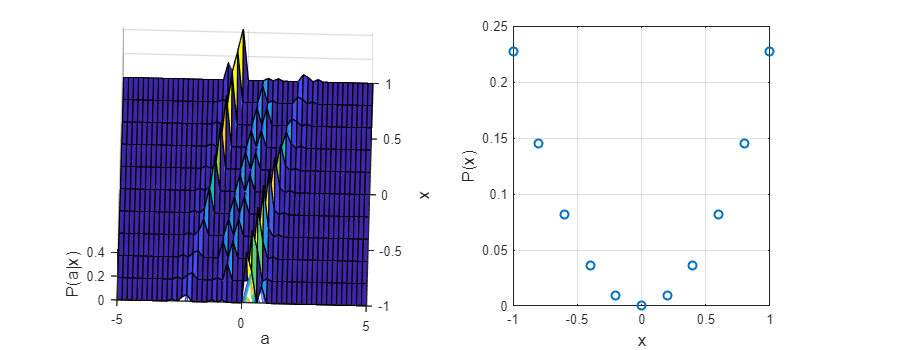

% plots
[A_mesh,X_mesh] = meshgrid(a_grid,x_grid);
cgf = figure;
set(gcf,'position',[0,0,900,350])
subplot(1,2,1)
surfc(A_mesh,X_mesh,pMatrix)
xlabel("a",FontSize=13)
ylabel("x",FontSize=13)
zlabel("P(a|x)",FontSize=13)
subplot(1,2,2)
plot(x_grid,x_P,'o',LineWidth=1.5);
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on

% The piece-wise mechanism
var_piecewise = @(ti) ti.^2./(exp(eps/2)-1) + (exp(eps/2)+3)/3/(exp(eps/2)-1)^2

var_piecewise = function_handle with value:
    @(ti)ti.^2./(exp(eps/2)-1)+(exp(eps/2)+3)/3/(exp(eps/2)-1)^2


var_piecewise(x_grid)

ans =     1.2276    1.0181    0.8551    0.7387    0.6689    0.6456    0.6689    0.7387    0.8551    1.0181    1.2276


variance_total_piecewise = var_piecewise(x_grid)*x_P'

variance_total_piecewise = 1.0600